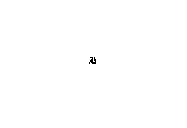

A = [1 0 0 0 1 0 1
     1 1 1 0 1 0 1
     1 1 0 0 1 0 0
     1 0 0 0 1 0 0
     1 0 0 0 1 1 0
     0 1 0 0 0 0 0
     0 1 1 0 0 0 0
     ];
 
B = bwskel(logical(A),"MinBranchLength",5);
imshow(A);

imshow(B);

## Testing on an image

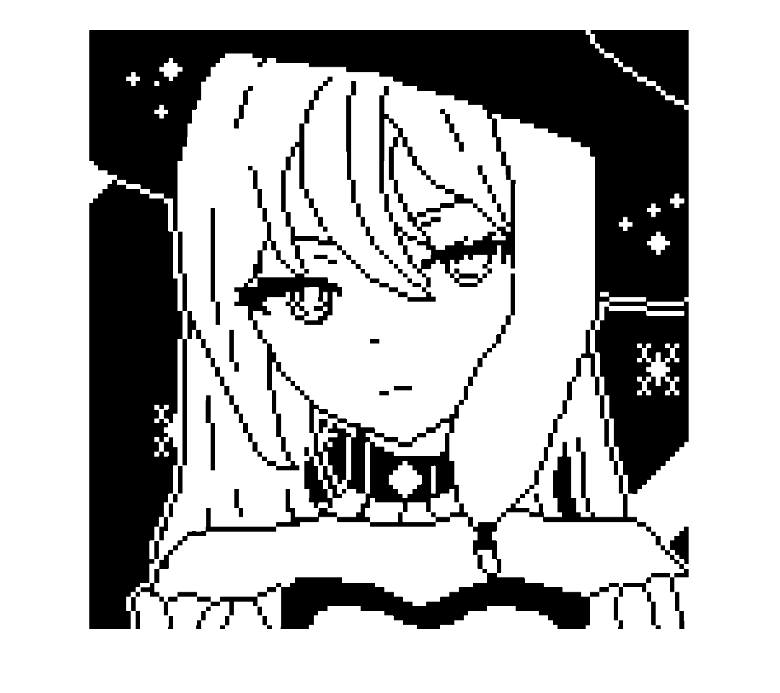

originalBW = imread('amine_girl.png');
%Create a flat, line-shaped structuring element.

se = strel('line',50,180);
%Erode the image with the structuring element.

erodedBW = imerode(originalBW,se);
%View the original image and the eroded image.

figure
imshow(originalBW)

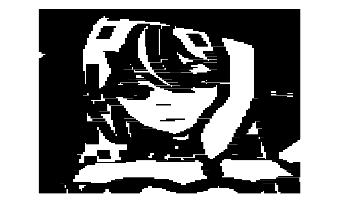

figure
imshow(erodedBW)

skel = erodedBW;
for i = 1:1:10
    skel = imerode(erodedBW,se);
end

figure
imshow(skel)

## Somethin gcomoletely different


for i = 150:1:500
    fprintf("trying: %d",i)
    if mod(20289,i) == 0
        fprintf("\nFound: %d\n",i);
    end
end

fprintf("END")

## Testing Peppers

image = load("Pepper_compressed.mat")

image = struct with fields:
    unpadded_resized_image: [120×160×3 uint8]


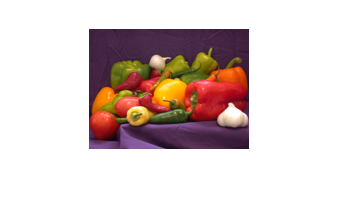

imshow(image.unpadded_resized_image)

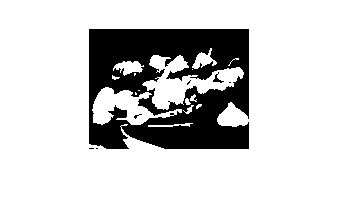

BW_image = im2bw(image.unpadded_resized_image,0.39);
imshow(BW_image);

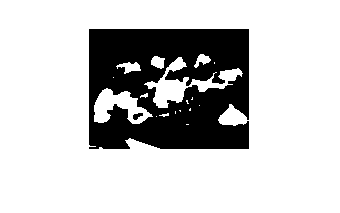


structuring_el = strel("square",3);

eroded_BW = imerode(BW_image,structuring_el);
imshow(eroded_BW);

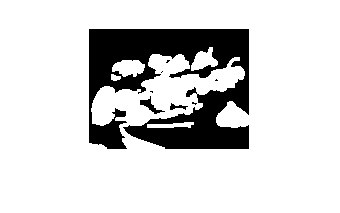

dilated_BW = imdilate(BW_image,structuring_el);
figure
imshow(dilated_BW)